# Laboratorio 9 de Febrero del 2023, Análisis Aplicado, ITAM

## Problema de Laczos2

A = lanczos2;

A =     2.5134         0
    2.0443    0.0500
    1.6684    0.1000
    1.3664    0.1500
    1.1232    0.2000
    0.9269    0.2500
    0.7679    0.3000
    0.6389    0.3500
    0.5338    0.4000
    0.4479    0.4500


t = A(:,2);
y = A(:, 1);
m = length(t);
plot(t,y, "rd", "LineWidth",3)
title("Prblema de Laczos2" , "FontSize",16)

fname = "funlanczos2";
x0 = [1.2 0.3 5.6 5.5 6.5 7.6]';
[xf, j ] = desnewton(fname, x0);

 1 19.97992014 
  2 5.40384761 
  3 0.98367624 
  4 0.04534588 
  5 0.01945361 
  6 0.00265957 
  7 0.12019685 
  8 0.03015369 
  9 0.29037369 
 10 0.03354682 
 11 0.00420623 
 12 0.00004277 
 13 0.00000525 
 

xf

xf =     2.4674
    3.7974
   -0.0002
    3.8351
   -0.0001
    3.8350


j

j = 13

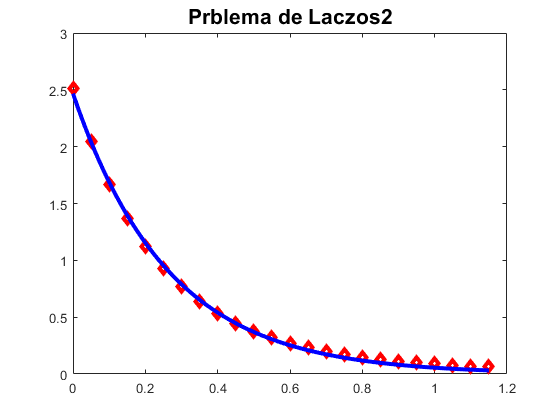

tt= linspace(min(t), max(t))';
hold on
z =  xf(1)*exp(-1*xf(2)*tt) + xf(3)*exp(-1*xf(4)*tt) + xf(5)*exp(-1*xf(6)*tt);
plot(tt,z,'b', "LineWidth",3)


fxf = funlanczos2(xf)

fxf = 0.0085